A = [1 2 -3;2 1 -3]

A =      1     2    -3
     2     1    -3


b = [2;-2]

b =      2
    -2


AM = [A b]

AM =      1     2    -3     2
     2     1    -3    -2


fprintf('The size of the augmented matrix: %dx%d', size(AM))

The size of the augmented matrix: 2x4

RAM = rref(AM)

RAM =      1     0    -1    -2
     0     1    -1     2


row1 = RAM (1, :)

row1 =      1     0    -1    -2


pivot_for_row1 = find(row1, 1)

pivot_for_row1 = 1

row2 = RAM(2, :)

row2 =      0     1    -1     2


pivot_for_row2 = find(row2, 1)

pivot_for_row2 = 2


%% Starter code with reference plane and axes in green.
clc, close all
figure
% Choose POLAR or CARTESIAN coordinates
use_polar_coordinates = true % options: true (polar) or false (cartesian)

use_polar_coordinates = logical
   1


% Choose a colormap.
% try other colormaps such as cool, hot, hsv, prism, flag, jet, parula, lines
colormap prism
% choose preferred shading for surface plots
shading faceted % Shading methods are faceted, flat, and interp.
L = 5 % A default limit so we can easily control the axes.

L = 5

% Set up a grid for each 3D plot.
x = -L : 1 : L; % x will range from -L to L.
y = -L : 1 : L; % y will range from -L to L.
[X,Y] = meshgrid(x,y);
% polar coordinates will be used instead, if you set use_polar_coordinates = true
if use_polar_coordinates
[rad,theta] = meshgrid(0:1:5, 0:2*pi/36: (2*pi) );
X = rad.*cos(theta);
Y = rad.*sin(theta);
Z = 0*X;
end
base = surf(X,Y,0*X + 0*Y); % Draw the xy plane. It's equation is z = 0.
hold on
grid on
%% add some transparency to the base (xy-plane) for reference
base.set('facealpha', 0.4); base.set('edgealpha', 0.15);
base.set('facecolor', 'green');
darkgreen = [0 0.5 0 ];
% Adjust the axes limits for optimal view
L = L + 1;
zmin = -L; zmax = +L; % these have to be set by trial and error.
axis([-L, L, -L, L, zmin, zmax]) % set all three axis limits - we are in three space
axis equal
% Plot the coordinate axis in the background as reference objects
t = [-1, 1] % used to compute endpoints along each axis

t =     -1     1


% plot the x-axis
x = L*t; y = 0*t; z = 0*t;
plot3( x, y, z, 'color', darkgreen, 'LineWidth', 3)
% plot the y-axis
x = 0*t; y = L*t; z = 0*t;
plot3( x, y, z, 'color', darkgreen, 'LineWidth', 3)
% plot the z-axis
x = 0*t; y = 0*t; z = [zmin, zmax]

z =     -6     6


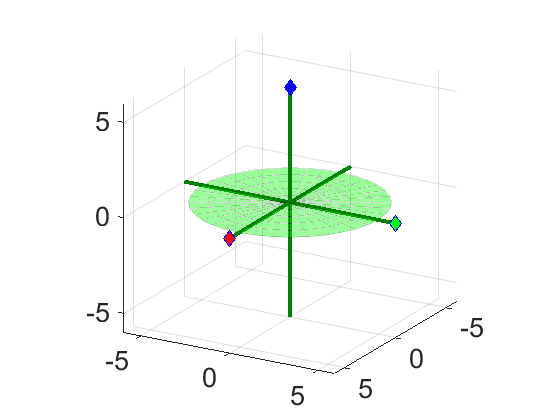

plot3( x, y, z, 'color', darkgreen, 'LineWidth', 3)
set(gca, 'FontSize', 20)
% Add one reference marker at the tip of the positive x-axis.
plot3( L, 0, 0, 'bd', 'MarkerSize', 9, 'MarkerFaceColor', 'red')
% Add one reference marker at the tip of the positive y-axis.
plot3( 0, L, 0, 'bd', 'MarkerSize', 9, 'MarkerFaceColor', 'green')
% Add one reference marker at the tip of the positive z-axis.
plot3( 0, 0, zmax, 'bd', 'MarkerSize', 9, 'MarkerFaceColor', 'blue')
view([120, 20])

%% Students will add more code here.

xlabel('x')
ylabel('y')
zlabel('z')
title('Visualization of a System of Equations')
z = -4 : 0.5 : 4; % New name for x3. Range restricted for clarity
x = z - 2;
y = z + 2;
% Plotting in 3D.
solution_set_as_line = plot3(x, y, z, 'blue-', 'LineWidth', 4)

solution_set_as_line =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 4
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-6 -5.5000 -5 -4.5000 -4 -3.5000 -3 -2.5000 -2 -1.5000 -1 -0.5000 0 0.5000 1 1.5000 2]
              YData: [-2 -1.5000 -1 -0.5000 0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6]
              ZData: [-4 -3.5000 -3 -2.5000 -2 -1.5000 -1 -0.5000 0 0.5000 1 1.5000 2 2.5000 3 3.5000 4]

  Show all properties


solution_set_as_points = plot3(x, y, z, 'blueo', 'LineWidth', 1)

solution_set_as_points =   Line with properties:

              Color: [0 0 1]
          LineStyle: 'none'
          LineWidth: 1
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-6 -5.5000 -5 -4.5000 -4 -3.5000 -3 -2.5000 -2 -1.5000 -1 -0.5000 0 0.5000 1 1.5000 2]
              YData: [-2 -1.5000 -1 -0.5000 0 0.5000 1 1.5000 2 2.5000 3 3.5000 4 4.5000 5 5.5000 6]
              ZData: [-4 -3.5000 -3 -2.5000 -2 -1.5000 -1 -0.5000 0 0.5000 1 1.5000 2 2.5000 3 3.5000 4]

  Show all properties


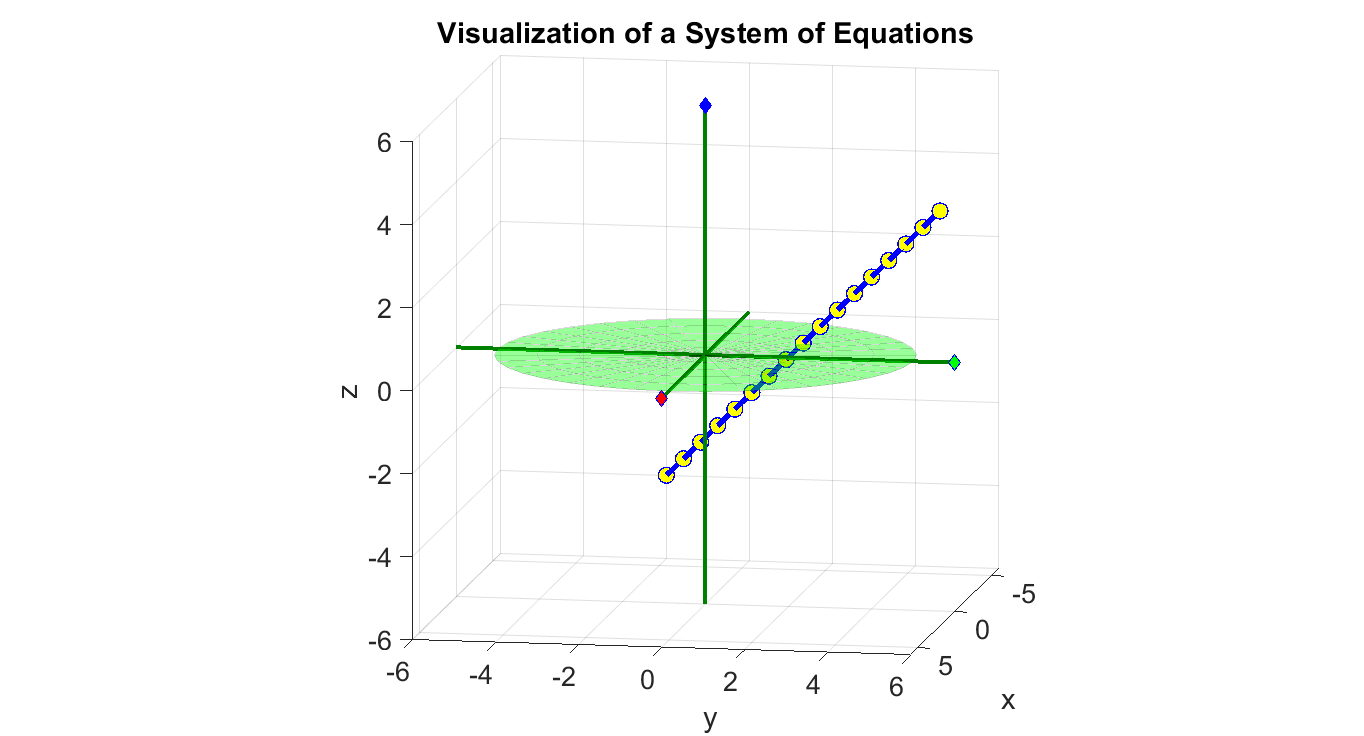

solution_set_as_points.set('MarkerFaceColor', 'yellow', 'MarkerSize', 12)
% Two ways to adjust the view, manually and programmatically.
rotate3d on; view([100, 10]); axis equal
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

%% Question 7-8 - Use surf command to show the two planes
% The meshgrid defined by arrays X and Y is still defined.
% We will use this to show each plane as a surface plot.

% First plane
a1 = A(1,1); a2 = A(1,2); a3 = A(1,3); d = b(1);
Z = (d - a1 * X - a2 * Y)/a3;
p1 = surf(X,Y,Z); % Draw the plane defined by the first equation.
p1.set('facealpha', 0.40)
a2 = A(2,1); a2 = A(2,2); a3 = A(2,3); d = b(2);
Z = (d - a1 * X - a2 * Y)/a3;
p2 = surf(X,Y,Z); % Draw the plane defined by the first equation.
p2.set('facealpha', 0.40)
p2.set('facealpha',0.40)
P1 = [ 4; 0; +5];
P2 = [ 4; 0; -5];
P3 = [ 0; -4; -5];
P4 = [ 0; -4; +5];
rect1= [P1 P2 P3 P4]

rect1 =      4     4     0     0
     0     0    -4    -4
     5    -5    -5     5


X = rect1(1, :); Y = rect1(2, :); Z = rect1(3, :);
plot3(X, Y, Z, 'bo', 'MarkerSize', 12 , 'MarkerFaceColor', 'blue')
rectangle = fill3(X, Y, Z, 'blue:')

rectangle =   Patch with properties:

    FaceColor: [0 0 1]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: ':'
        Faces: [1 2 3 4]
     Vertices: [4×3 double]

  Show all properties


rectangle.set('facealpha', 0.4)
Q1 = [ 0; 4; +5];
Q2 = [ 0; 4; -5];
Q3 = [ -4; 0; -5];
Q4 = [ -4; 0; +5];
rect2 = [Q1 Q2 Q3 Q4]

rect2 =      0     0    -4    -4
     4     4     0     0
     5    -5    -5     5


X = rect2(1, :);Y = rect2(2, :); Z = rect2(3, :);
plot3(X,Y,Z, 'bo','Markersize',12 ,'MarkerFaceColor', 'magenta')
rectangle = fill3(X,Y,Z,'magenta:')

rectangle =   Patch with properties:

    FaceColor: [1 0 1]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: ':'
        Faces: [1 2 3 4]
     Vertices: [4×3 double]

  Show all properties


rectangle.set('facealpha',0.4)

A = [1 2 -3;2 1 -3;1 -1 0]

A =      1     2    -3
     2     1    -3
     1    -1     0


b = [2;-2;4]

b =      2
    -2
     4


AM = [A b]

AM =      1     2    -3     2
     2     1    -3    -2
     1    -1     0     4


RAM2 = rref(AM)

RAM2 =      1     0    -1     0
     0     1    -1     0
     0     0     0     1



A = [1 2 -3;2 1 -3;1 -1 0]

A =      1     2    -3
     2     1    -3
     1    -1     0


b = [2;-2;-4]

b =      2
    -2
    -4


AM = [A b]

AM =      1     2    -3     2
     2     1    -3    -2
     1    -1     0    -4


RAM3 = rref(AM)

RAM3 =      1     0    -1    -2
     0     1    -1     2
     0     0     0     0



N = 2; % Number of complete revolutions of the azimuth. Elevation fixed at 20.
elevation = 20

elevation = 20

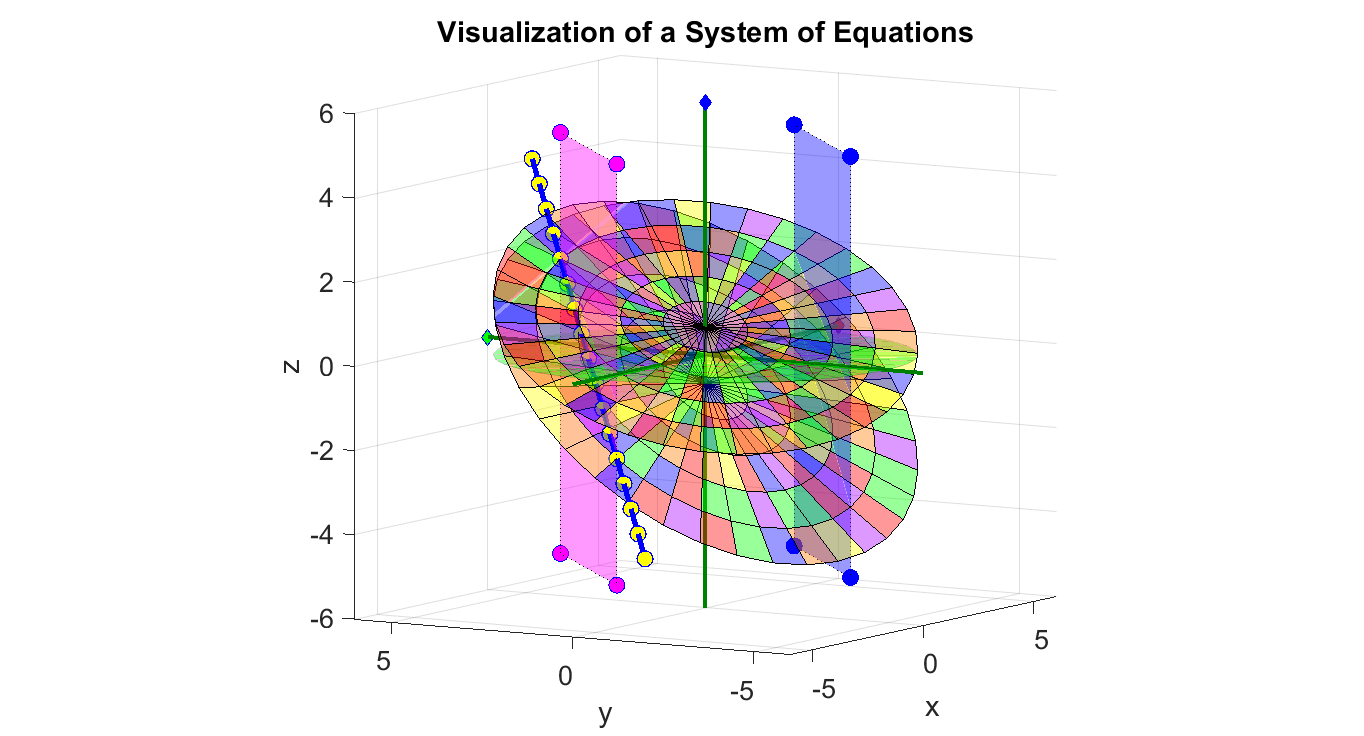

for  k =0:1:360 *N
    view([k,elevation])
     pause(0.05)
end